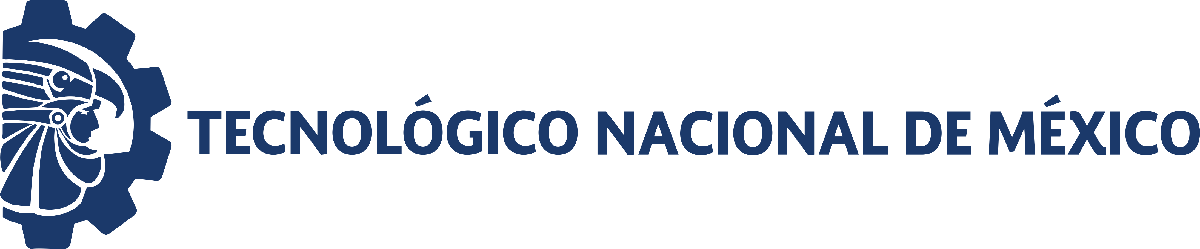                                 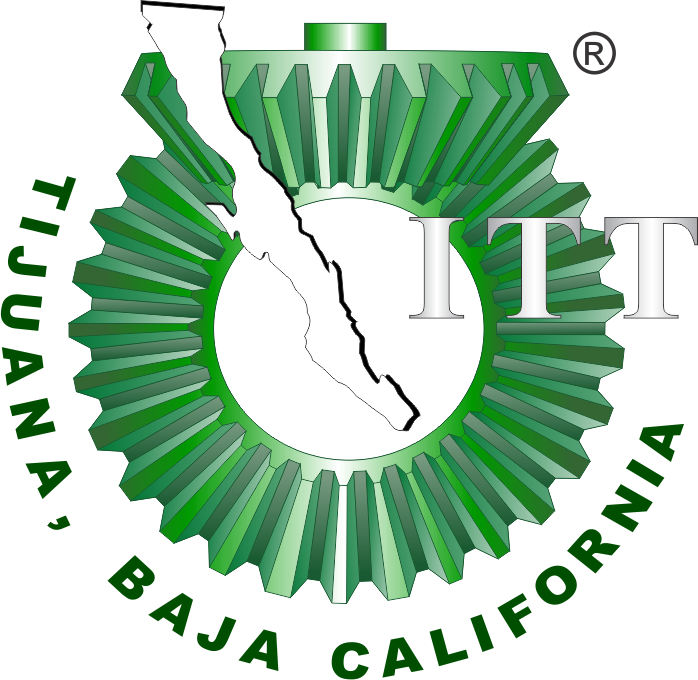

# Práctica tres: Sistema Musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

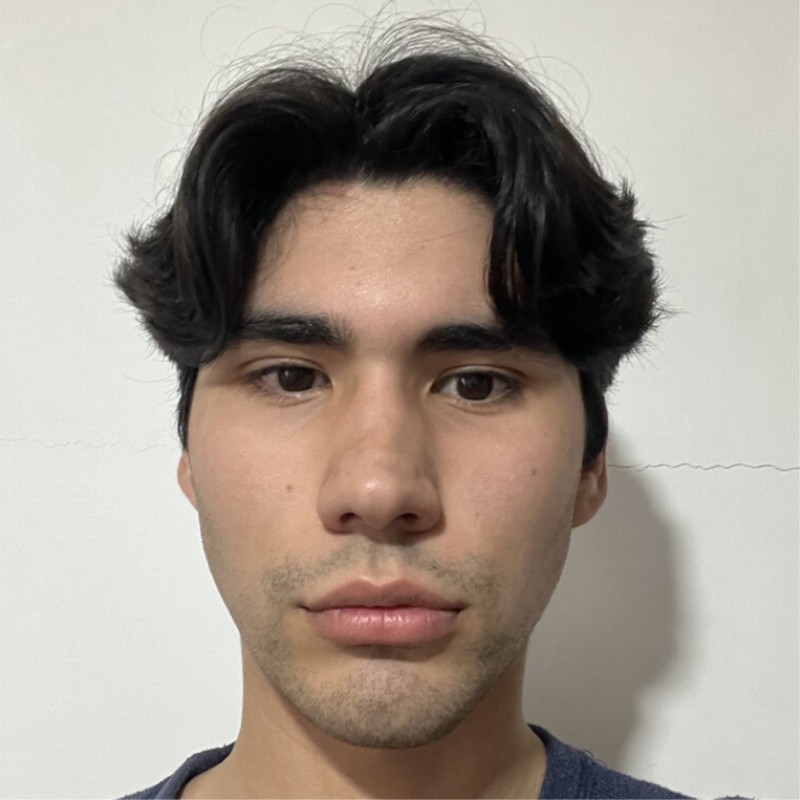

Nombre del alumno: Alberto Villalobos Valdez

Número de control: 22212277

Correo institucional: L22212277**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

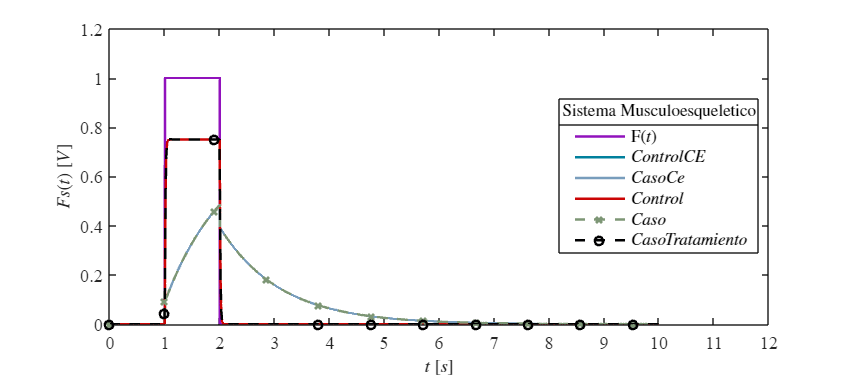

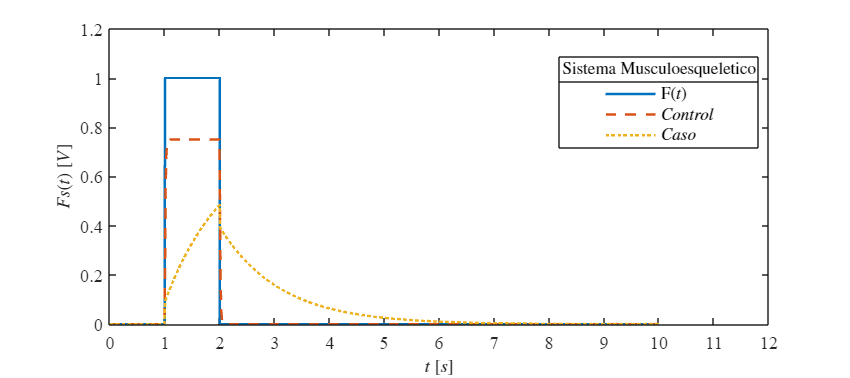

clc; clear; close all; warning('off','all');
tend = '10';
file = 'sistemaa';
open_system(file);
parameters.StopTime=tend;
parameters.Solver = "ode23t";
parameters.MaxStep = '1E-3';
set_param('sistemaa/F(t)','PulseType','Time based');
set_param('sistemaa/F(t)','TimeSource','Use simulation time');
set_param('sistemaa/F(t)','Amplitude','1');
set_param('sistemaa/F(t)','Period','10');
set_param('sistemaa/F(t)','PulseWidth','10');
set_param('sistemaa/F(t)','PhaseDelay','1');

x1=sim(file,parameters);
writematrix(x1.Ft, 'signal.xlsx')
plotsignals(x1.t,x1.Ft,x1.Fs0,x1.Fs1,x1.Fs2,x1.Fs3,x1.PID);

## Funcion : Respuesta a las señales

function plotsignals(t,Ft,Fs0,Fs1,Fs2,Fs3,PID)
    set(figure(), 'Color', 'w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    
    mycolors=[145,18,188;
        0,128,157;
        120,157,188;
        203,4,4;
        125,150,117;
        0,0,1]/255;

    colororder(mycolors)
    plot(t,Ft,'-',t,Fs0,'-',t,Fs1,'-',t,Fs2,'-',t,Fs3,'--x',t,PID,'--o',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    L= legend('F$(t)$','$ControlCE$','$CasoCe$','$Control$','$Caso$','$Caso Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','Best','Box','On');
    title(L,'Sistema Musculoesqueletico', 'FontSize',10)
    xlabel('$t$ $[s]$', 'Interpreter','Latex','FontSize',11)
    ylabel('$Fs(t)$ $[V]$', 'Interpreter','Latex','FontSize',11)
    xlim([0,12]); xticks(0:1:12);
    ylim([0,1.2]); yticks(0:0.2:1.4)
    exportgraphics(gcf,['SistemaMELC.pdf'],'ContentType','vector');
    exportgraphics(gcf,['SistemaMELC.png'],'ContentType','vector');
    set(figure(), 'Color', 'w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    plot(t,Ft,'-',t,Fs0,'--',t,Fs1,':',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    L= legend('F$(t)$','$Control$','$Caso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','Best','Box','On');
    title(L,'Sistema Musculoesqueletico', 'FontSize',10)
    xlabel('$t$ $[s]$', 'Interpreter','Latex','FontSize',11)
    ylabel('$Fs(t)$ $[V]$', 'Interpreter','Latex','FontSize',11)
    xlim([0,12]); xticks(0:1:12);
    ylim([0,1.2]); yticks(0:0.2:1.4)
    exportgraphics(gcf,['SistemaMELA.pdf'],'ContentType','vector');
    exportgraphics(gcf,['SistemaMELA.png'],'ContentType','vector');
 
end


